#               Antenna Array Processing

##                                            HW5

                 Mohammadreza Arani         :::::::::::::         810100511

                                                            1401/08/24           

clear; clc; close all;

We did find out that we can consume Bandwidth as  a remedy for not increasing/decreasing pulse width (tau)!

==> One workaround is to use an up/down chirp signal instead of a rectangular pulse! -->  These techniques are called pulse compression! ==> Mostly used by radars, sonar and echography!

Pulse compression is a method for improving the [range resolution](https://www.radartutorial.eu/01.basics/Range%20Resolution.en.html) of [pulse radar](https://www.radartutorial.eu/02.basics/Pulse%20Radar.en.html). This method is also known as intra-pulse modulation (modulation on pulse, MOP) because the transmitted pulse got a time-dependent modulation internally. The term CHIRP–Radar is often used in publications (**C**ompressed, **HI**gh-**R**esolution **P**ulse, CHIRP). 

Common methods for signal/pulse compression:

- frequency modulated (or called  **Frequency Modulation on Pulse, FMOP**) 

- phase modulated (or called **Phase Modulation on Pulse, PMOP**) 

    1) Chirping (Linear Frequency Modulation)

    2) Phase Coding

    3)  Non-Linear Frequency Modulation

The Pulse Compression Ratio (PCR) is the ratio of the time length of the uncompressed transmitted pulse to the length of the compressed pulse.

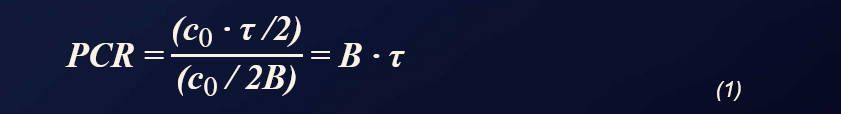

The range resolution of a pulse modulated radar is therefore a multiple (by a factor of the Pulse Compression Rate PCR) of the range resolution of an intra-pulse modulated radar:

### Initialization:

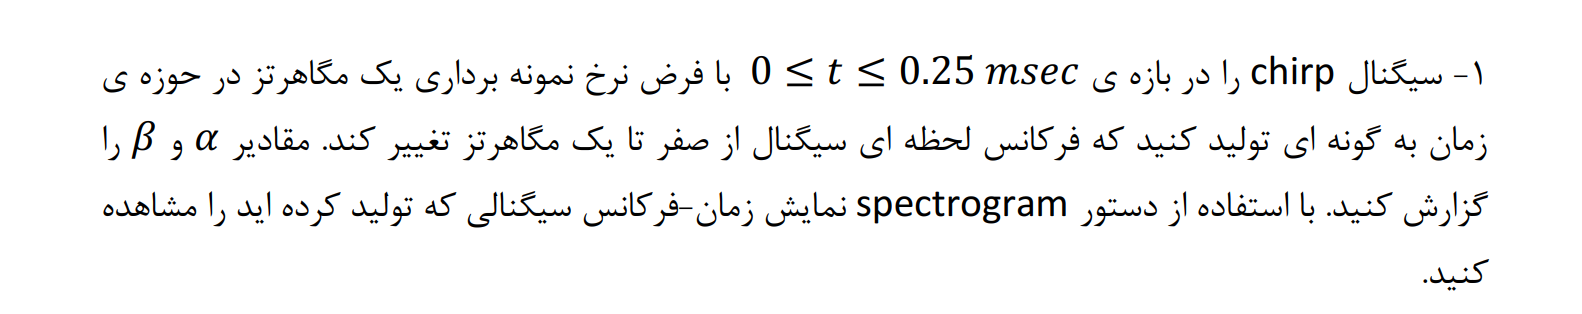

% Signals are considered to be in Low Frequency Band
ts =  1e-5; % --> to get 1 MHz --> 
fs=1/ts; % sampling rate --> 100Hz
C=300e6; % light speed

Tau_length = 0.25e-3;  % 0.25ms

tau_num=round(Tau_length/ts);  % --> Consider a single sample on the signal
tau=tau_num*ts; % --> the signal length would be equal to number of samples multiplied by length of each sample!

PRI=2.5e-3; % 2.5 ms
PRI_num=round(PRI/ts); % --> number of sqaured pulses in signal

PRF=1/PRI;

A=1;


Trecording=1 * PRI;   % --> Recording time at the receiver!

deltaf=1/Trecording; % Frequency Resolution

pulse_num=round(Trecording/PRI); % Number of pulse in recording time
sample_num=round(Trecording/ts);

t=0:ts:Trecording-ts; % Time Vector 
freq=-fs/2:deltaf:fs/2-deltaf; % Frequency Vector

tpulse = 0:ts:Tau_length-ts ; % 1 Pulse!

Beta = 0; % at time 0 the bandwidth and the frequency is 0
Alpha = 1e6/(2*Tau_length) ; % shall reach 2*tau*Alpha = 1 MHz --> tau = 25e-5 ==> Alpha = 1e6/(2*tau)
chirp_freq = 2*Alpha*tpulse+Beta;

disp("Alpha is equal to: "+Alpha+" and Beta is equal to: "+Beta)

Alpha is equal to: 2000000000 and Beta is equal to: 0



% Create Our Signal : The one Pulse:


Signal_base = exp(1j*2*pi*(Alpha*tpulse.^2+Beta*tpulse))  ;

SL_PRI=A* [Signal_base.*ones(1,tau_num) zeros(1,PRI_num-tau_num)]; % single pulse in the interval of sending and receiving
sl=repmat(SL_PRI,1,pulse_num); % Repeated pulse for each PRI in Trecording

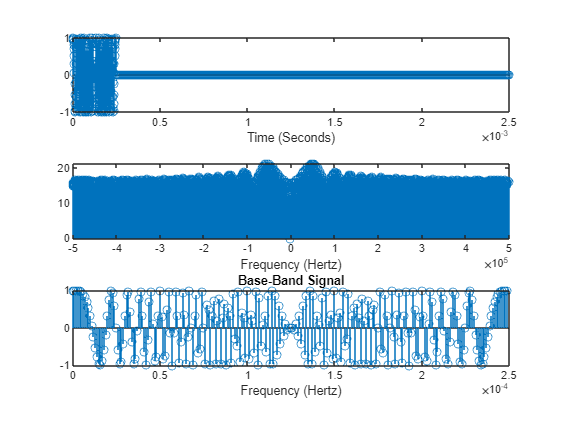

figure(1)
subplot(3,1,1)
stem(t,real(sl)) % The Signal itself --> Signal_base band
xlabel('Time (Seconds)')
subplot(3,1,2)
slf=fftshift(fft(sl)); % shifted fft signal --> Fourier transformation --> I expect to see the sampled form of the expected Fourier transform with the distance of 1/PRI = PRF
stem(freq,abs(slf)) % Frequency Domain
xlabel('Frequency (Hertz)')
subplot(3,1,3)
stem(tpulse,real(Signal_base))
xlabel('Frequency (Hertz)')
title("Base-Band Signal")

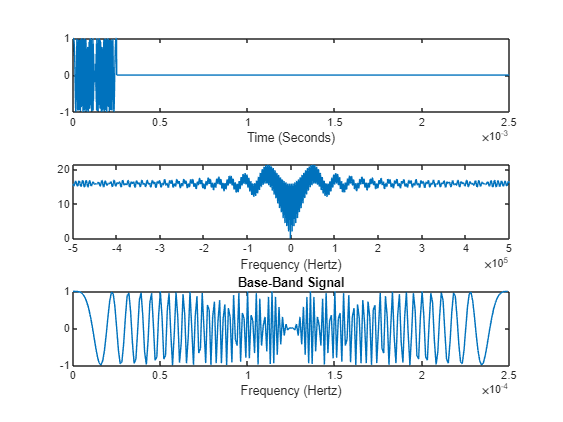

% To have a better look --> use Plot instead:
figure(1)
subplot(3,1,1)
plot(t,real(sl)) % The Signal itself --> Signal_base band
xlabel('Time (Seconds)')
subplot(3,1,2)
slf=fftshift(fft(sl)); % shifted fft signal --> Fourier transformation --> I expect to see the sampled form of the expected Fourier transform with the distance of 1/PRI = PRF
plot(freq,abs(slf)) % Frequency Domain
xlabel('Frequency (Hertz)')
subplot(3,1,3)
plot(tpulse,real(Signal_base))
xlabel('Frequency (Hertz)')
title("Base-Band Signal")

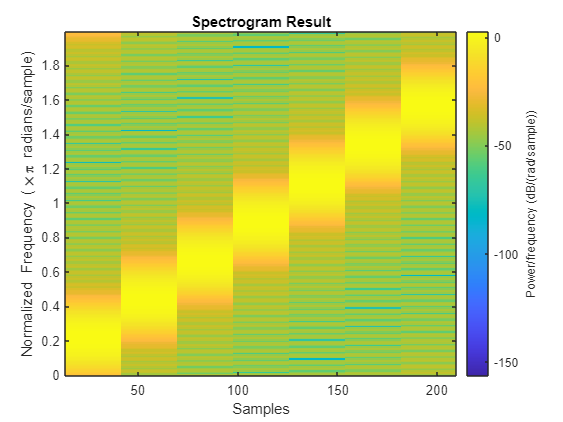

figure()
spectrogram(Signal_base,'yaxis')
title("Spectrogram Result")

The signal in Frequency domain can be seen above in comparison to its samples! --> linear frequency increase in the pulse/Signal is obvious!

## 2-Correlation of Signal with its shifted forms!

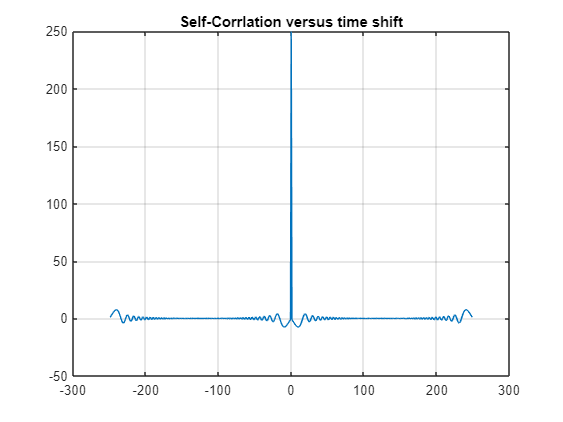

% Correlation can be implemented using xcorr in MATLAB:

[ Self_Correlation , time_vec ] = xcorr(Signal_base) ;
% Plot the correlation:
figure()
plot(time_vec , real(Self_Correlation) )
grid on
title("Self-Corrlation versus time shift")

It can be said, with respect to above figure, that the signal is almost perpendicular/independent to its shifted forms due to low correlation with its shifted forms!

The reason that the correlation is so less than previous pulse shape (rectangular) is that, the frequency is increasing and varies as the time goes on, making each shifted-sample of the signal become discernible in frequency domain and so to be distinguished easily!

- Also, we need to understand that exp(1j*2*pi*fn*t) are independent in frequency domain meaning <Sn, Sm > = 0; for m ~=n !

## 3- Pulse-Train of up-chirp


SL_PRI2=A* [Signal_base.*ones(1,tau_num) zeros(1,PRI_num-tau_num)]; % single pulse in the interval of sending and receiving
sl2=repmat(SL_PRI2,1,pulse_num); % Repeated pulse for each PRI in Trecording


% define td and fd vectors as mentioned in the first question:
delay_vector = -PRI : ts : PRI ;
doppler_freq_vector = -4e3: 1 : 4e3 ; % 8000Hz with 1Hz resolution

P = zeros(length(doppler_freq_vector),length(delay_vector));

for i=1:length(delay_vector)
    for j=1:length(doppler_freq_vector)
        td = delay_vector(i) ;
        fd = doppler_freq_vector(j);
        P(j,i) = sum(sl2.*conj(circshift(sl2,round(td/ts))) .* exp(-1j*2*pi*fd.*t)) ;  % sl(t)*sl(t-td)^ * exp(-1j*2*pi*fd*t) --> summation on t


    end
end

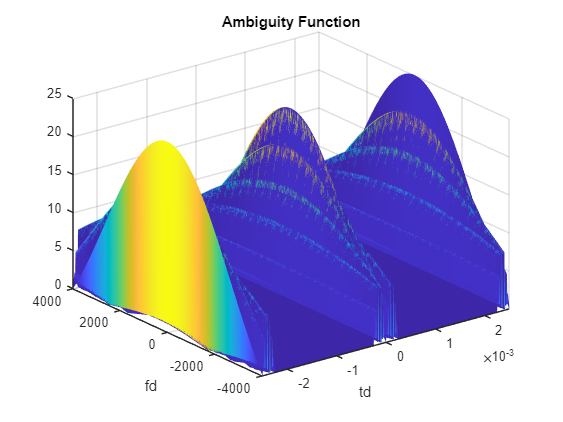

[TD,FD] = meshgrid(delay_vector , doppler_freq_vector) ; % Baze o motegharen greftam... Nemidunestam manzur ghesmate manfias ya mosbataro ham nesfe konam

figure()
h=surf(TD,FD,abs(P));
xlabel("td")
ylabel("fd")
title("Ambiguity Function")
set(h,'LineStyle','none')

## 4-Draw the plane where fd=0+td=0:

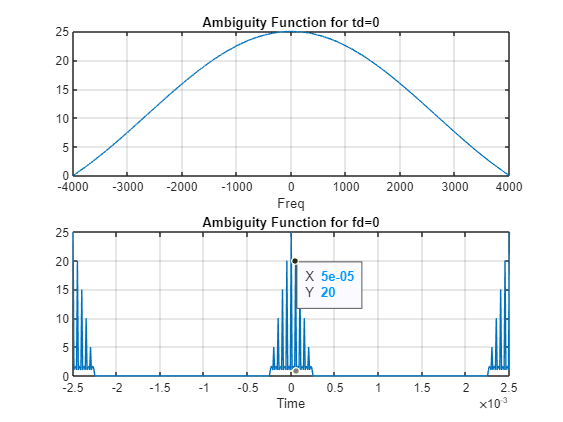

figure()
subplot(2,1,1)
plot(doppler_freq_vector,abs(P(:,round(  length(P(1,:))/2   ) ) )         );
xlabel("Freq")
title("Ambiguity Function for td=0")
grid on
subplot(2,1,2)
plot(delay_vector,abs(P(round(  length(P(:,1))/2   )  , :) )         );
xlabel("Time")
title("Ambiguity Function for fd=0")
grid on

As mentioned in the previous HW (4) --> at fd=0  we get: 

The $p\left(0,f_d \right)=\mathrm{conv}\left(A,A\right);$ --> which is the correlation we computed in the second part! --> so close to delta form! without reducing the tau!


$$p\left(t_d ,0\right)={\mathrm{rep}}_{\mathrm{PRI}} \left(\;\;\;\;\;\;\mathrm{conv}\left(\Pi \left(\frac{t}{\tau }\right),\Pi \left(\frac{t}{\tau }\right)\;\;\right)\;\;\;\;\;\right)-----\to \mathrm{conv}\left(\Lambda \left(\frac{t}{\tau }\right)\;,\;\Sigma \left(\delta \;\left(t-n*\mathrm{PRI}\right)\right)\right)\;=\Sigma \Lambda \left(\frac{\left(t-n*\mathrm{PRI}\right)}{\tau }\right)\;$$


Peaks are repated every PRF in Frequency domain and every PRI in Time domain!

Nulls distance is close to 1e-7 in fd=0 plane! --> a better distance rather than previously acquired Null Distance in Hw4!

Part 5:

Doppler space resolution only depends on Trecord and it has been intact and so the doppler resolution (40Hz)!

## 6-Question:

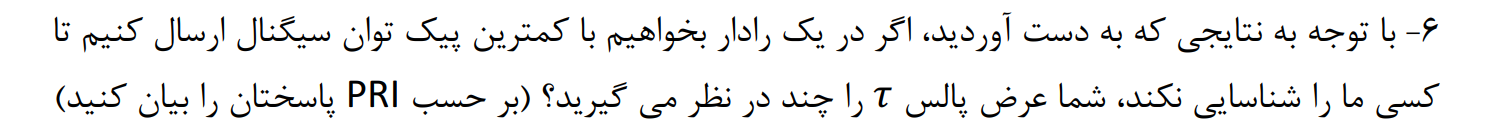

By Increase in Tau, we may lose range resolution if we choose to have rectangular pulse --> 

increase in Tau results in lower BW in frequency domain and so the Range Resolution will be dropped!

Now that we are using an Up-chirp signal, we can extend the Tau but increasing the Band-width of the signal! --> The Ideal Value for Tau is to be the same as PRI -->

100% of PRI is occupied by our pulse! --> we have to control the band-width using pulse compression!